Conclusion: Our Error Converges To 2nd Order Degree, Given We can Fit it With a 2nd Order Polynomial. 

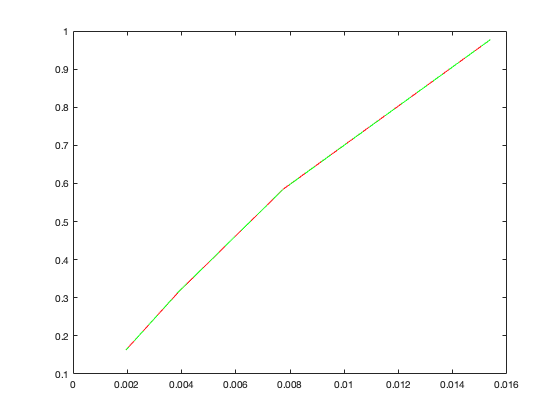



LinfErr = zeros(1,4);
dxv = zeros(1,4);

for ind = 1:4

%x Boundaries
xlow = 0;
xup = 1;

%Parameter a
a = 1;

%Interior
m = [64,128,256,512];

%Total With Boundaries
N = m(ind) + 2;

%Create x & dx
x = linspace(xlow, xup, N)';
dx = x(2) - x(1);

%Time Boundaries
t = 0;
T = 8;

%Step Vector & Drawing frequency
dt = 0.8 * dx;
n_steps = round(T / dt);
n_draw = round(0.01*n_steps);

% We Implement BW W/ a>0
u_bw = [u_init(x); 0; 0];

%Set Ghost Cells to Initial
u_bw(length(u_bw)-1) = u_bw(1);

I2 = 3:N+2;

error = zeros(1,length(n_steps));

for n = 1:n_steps
    
    u_bw(I2) = u_bw(I2) - 0.5 * a * dt / dx * (3 * u_bw(I2) -4 * u_bw(I2-1) + u_bw(I2-2)) + (0.5 * a^2 * dt^2 / dx^2) * ( u_bw(I2) - 2 * u_bw(I2-1) + u_bw(I2-2));
    
    u_bw(1) = u_bw(length(u_bw)-1);
    u_bw(2) = u_bw(length(u_bw));
    
    t = t + dt;
    
    ux = u_exact(@u_init,x,a,t,xup);
    error(1,n) = max(abs(u_bw(3:end,1) - ux));
end

LinfErr(1,ind) = max(error);
dxv(1,ind) = dx;
end

plot(dxv,LinfErr,'r');
hold on;

%2nd Order Polynomial 
f = polyfit(dxv,LinfErr,2);

plot(dxv,polyval(f,dxv),'g--');

function u = u_exact(u_init, x, a, t, xmax)

% Exact solution. Assumes xlow = 0
xat = rem(x - a*t, xmax);
ineg = find(xat < 0);
xat(ineg) = xat(ineg) + xmax;
u = u_init(xat);

end

function u = u_init(x)

u = exp(-100*(x-0.5).^2);

end